# Project 2 Credit Risk - Xinyi (Cynthia) Shen

Student Number: 1005778428

clc, clear all, close all
rng(0);

## Problem

Consider a portfolio of two BBB bonds with two different counterparties, with marginal default probabilities given by the table below, and a dependence structure given by:

- A. A multivariate Gaussian distribution with a correlation of 0.5

- B. A Gaussian copula with correlation of 0.5

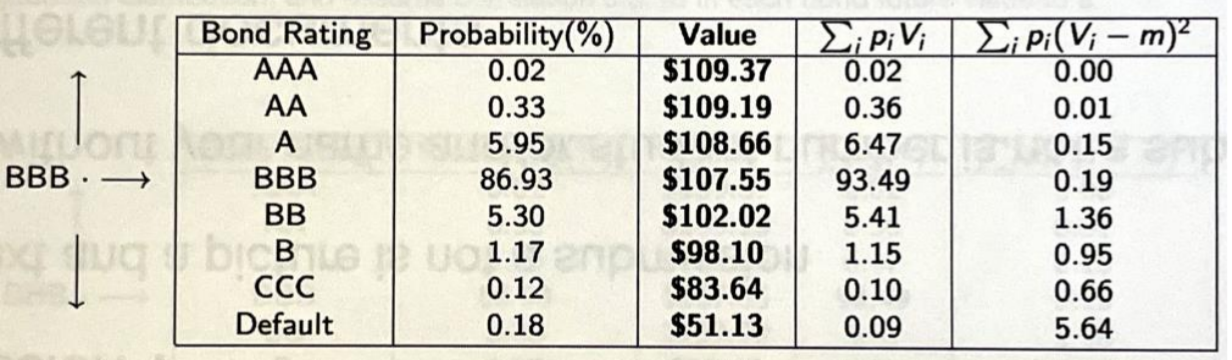

Simulate one million future portfolio values to calculate the expected credit loss and the 99% percentile of the loss distribution.

Compare A and B above. Which one produces the highest loss prediction? Can you tell why?

Now imagine you had 10 of these bonds. What would the 99% percentile of the expected credit loss look like? What about 100 bonds? Draw a graph of the 99% percentile loss against the number of bonds. Label it well.

### Model Setup

Useful bond rating information:

BondRating = ["AAA", "AA", "A", "BBB", "BB", "B", "C", "Default"];
Probability = [0.02 0.33 5.95 86.93 5.30 1.17 0.12 0.18] / 100;
CumProbability = cumsum(Probability,2,"reverse")';
BondValue = [109.37 109.19 108.66 107.55 102.02 98.10 83.64 51.13];
ExpectedValue = Probability .* BondValue;
Variance = Probability .* (BondValue - sum(ExpectedValue)).^2;

Pull a table to gather the information:

TblBond = table;
TblBond.BondRating = BondRating';
TblBond.Probability = Probability';
TblBond.CumProbability = CumProbability;
TblBond.BondValue = BondValue';
TblBond.ExpectedValue = ExpectedValue';
TblBond.Variance = Variance';

Define the boundareis of the Z-matrix to model transitions

% Define the Marginal Distribution as N(0,1)
ZDefault = norminv(TblBond.Probability(8), 0, 1);
ZC = norminv(sum(TblBond.Probability(7:8)), 0, 1);
ZB = norminv(sum(TblBond.Probability(6:8)), 0, 1);
ZBB = norminv(sum(TblBond.Probability(5:8)), 0, 1);
ZBBB = norminv(sum(TblBond.Probability(4:8)), 0, 1);
ZA = norminv(sum(TblBond.Probability(3:8)), 0, 1);
ZAA = norminv(sum(TblBond.Probability(2:8)), 0, 1);
ZAAA = norminv(sum(TblBond.Probability(1:8)), 0, 1);
ZBoundary = [ZAAA, ZAA, ZA, ZBBB, ZBB, ZB, ZC, ZDefault];
 
% Add to table
TblBond.Z = ZBoundary'

TblBond = 8×7 table
    BondRating    Probability    CumProbability    BondValue    ExpectedValue    Variance        Z   
    __________    ___________    ______________    _________    _____________    _________    _______

    "AAA"           0.0002                1         109.37        0.021874       0.0010416        NaN
    "AA"            0.0033           0.9998         109.19         0.36033        0.014582     3.5401
    "A"             0.0595           0.9965         108.66          6.4653         0.14705     2.6968
    "BBB"           0.8693            0.937         107.55          93.493         0.18561     1.5301
    "BB"             0.053           0.0677         102.02          5.4071          1.3612    -1.4931
    "B"             0.0117 

### Dependence Structure

% Number of simulations
N = 1e6;

% Correlation for BBB bonds
DefaultRho = 0.5;
CDEP = [1, DefaultRho; DefaultRho, 1];

#### A. A Multivariate Gaussian Distribution with a Correlation of 0.5

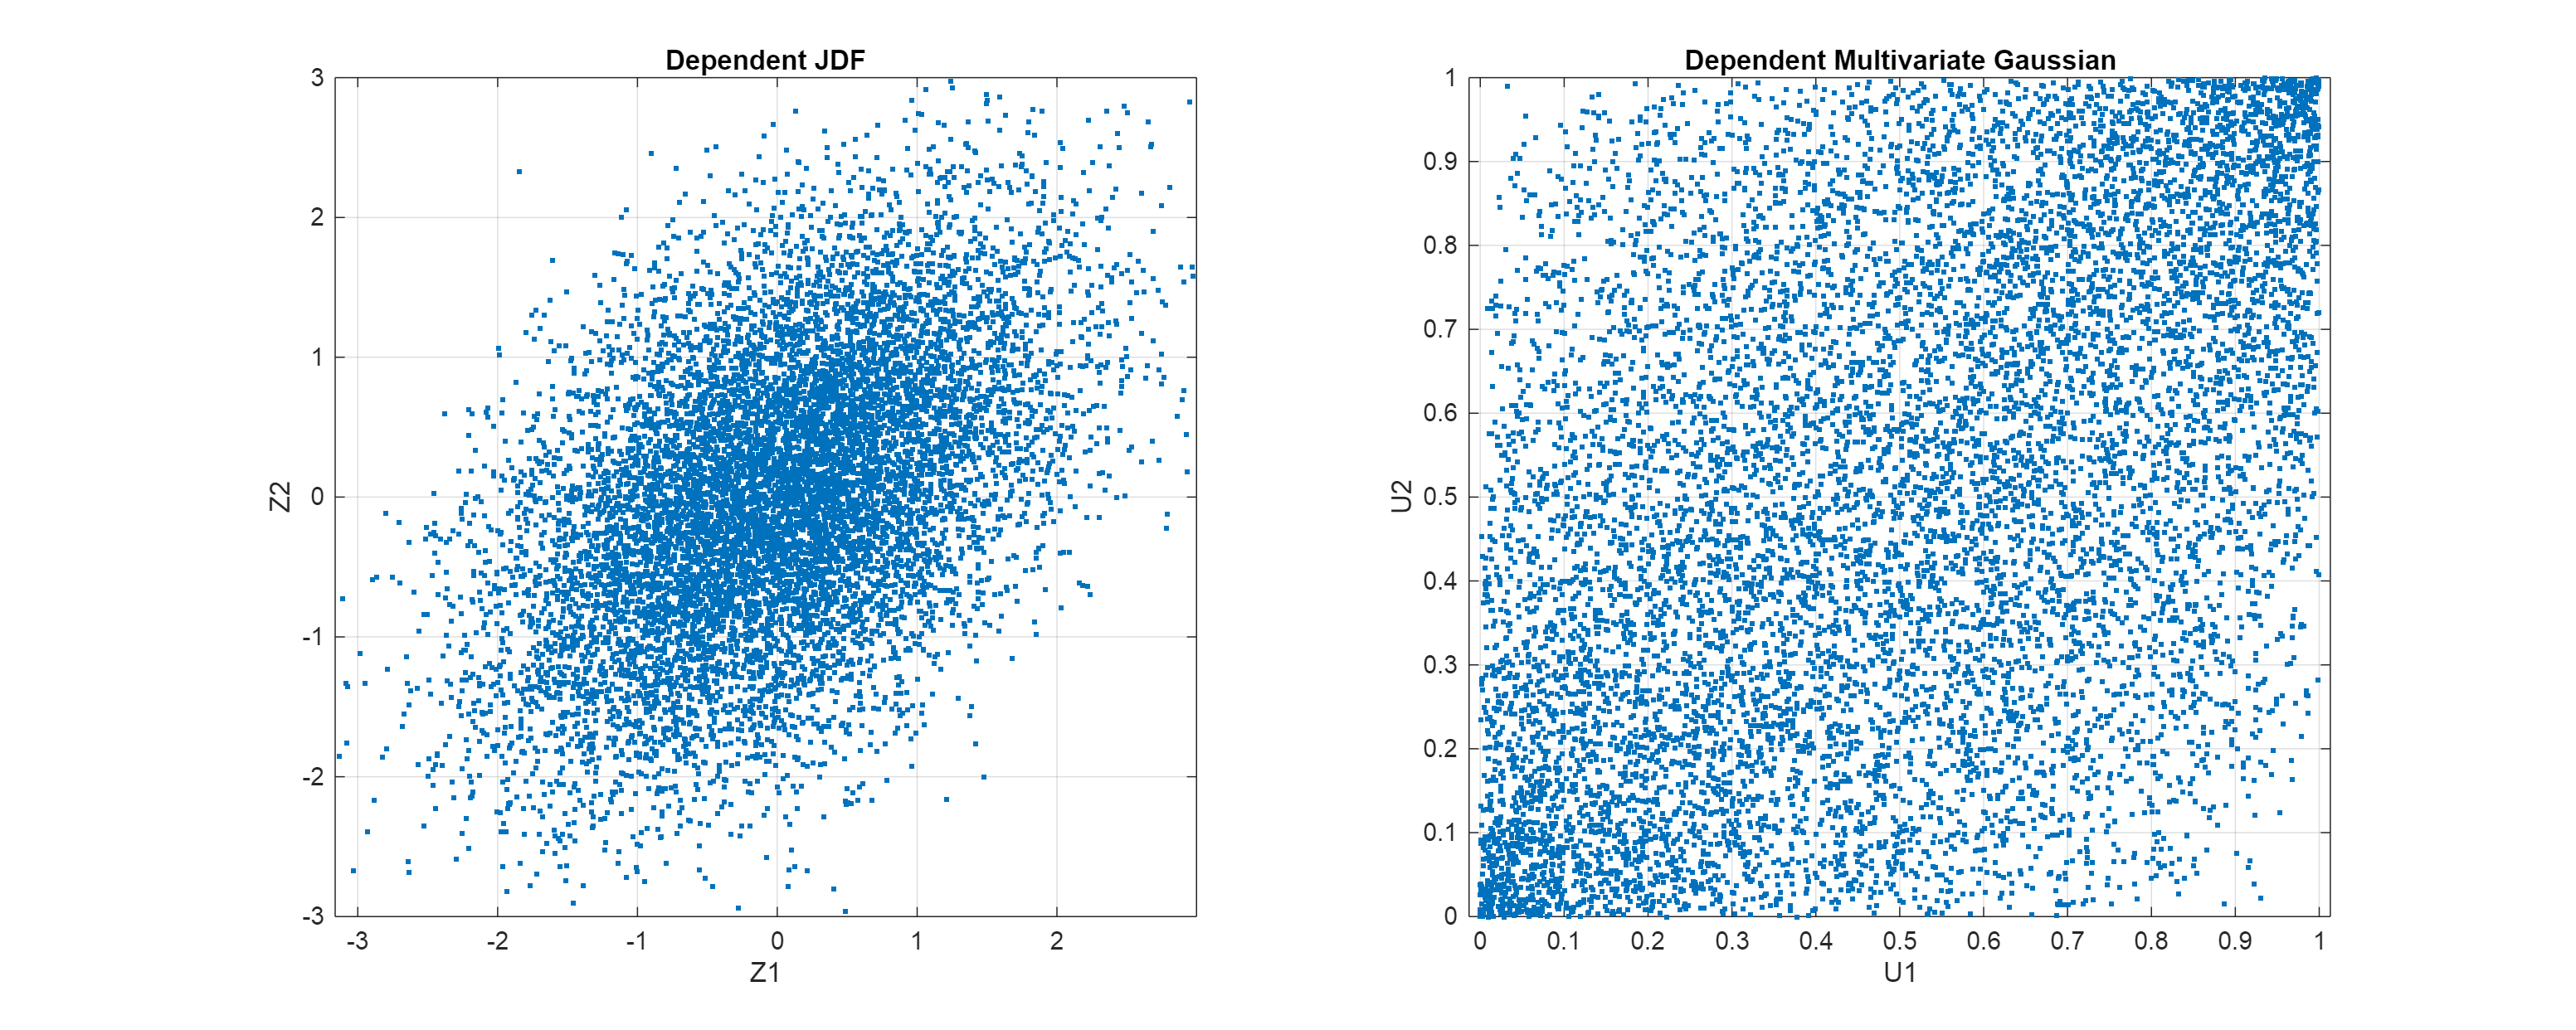

% Multivariate Approach
ZDEP_MultiGaussian = mvnrnd([0 0], CDEP, N);
UDEP_MultiGaussian = normcdf(ZDEP_MultiGaussian);

% Graphs and Results
ISample = 1:10000; % to reduce the memory to display scatterplots
 
figure()
set(gcf, 'Position', [0,0,1500,600])
 
subplot(1,2,1)
plot(ZDEP_MultiGaussian(ISample,1), ZDEP_MultiGaussian(ISample,2), '.')
axis([-3 3 -3 3])
axis equal
grid on
title('Dependent JDF')
xlabel('Z1')
ylabel('Z2')
 
subplot(1,2,2)
plot(UDEP_MultiGaussian(ISample,1), UDEP_MultiGaussian(ISample,2), '.')
axis([0 1 0 1])
axis equal
grid on
title('Dependent Multivariate Gaussian')
xlabel('U1')
ylabel('U2')

#### B. A Gaussian Copula with Correlation of 0.5

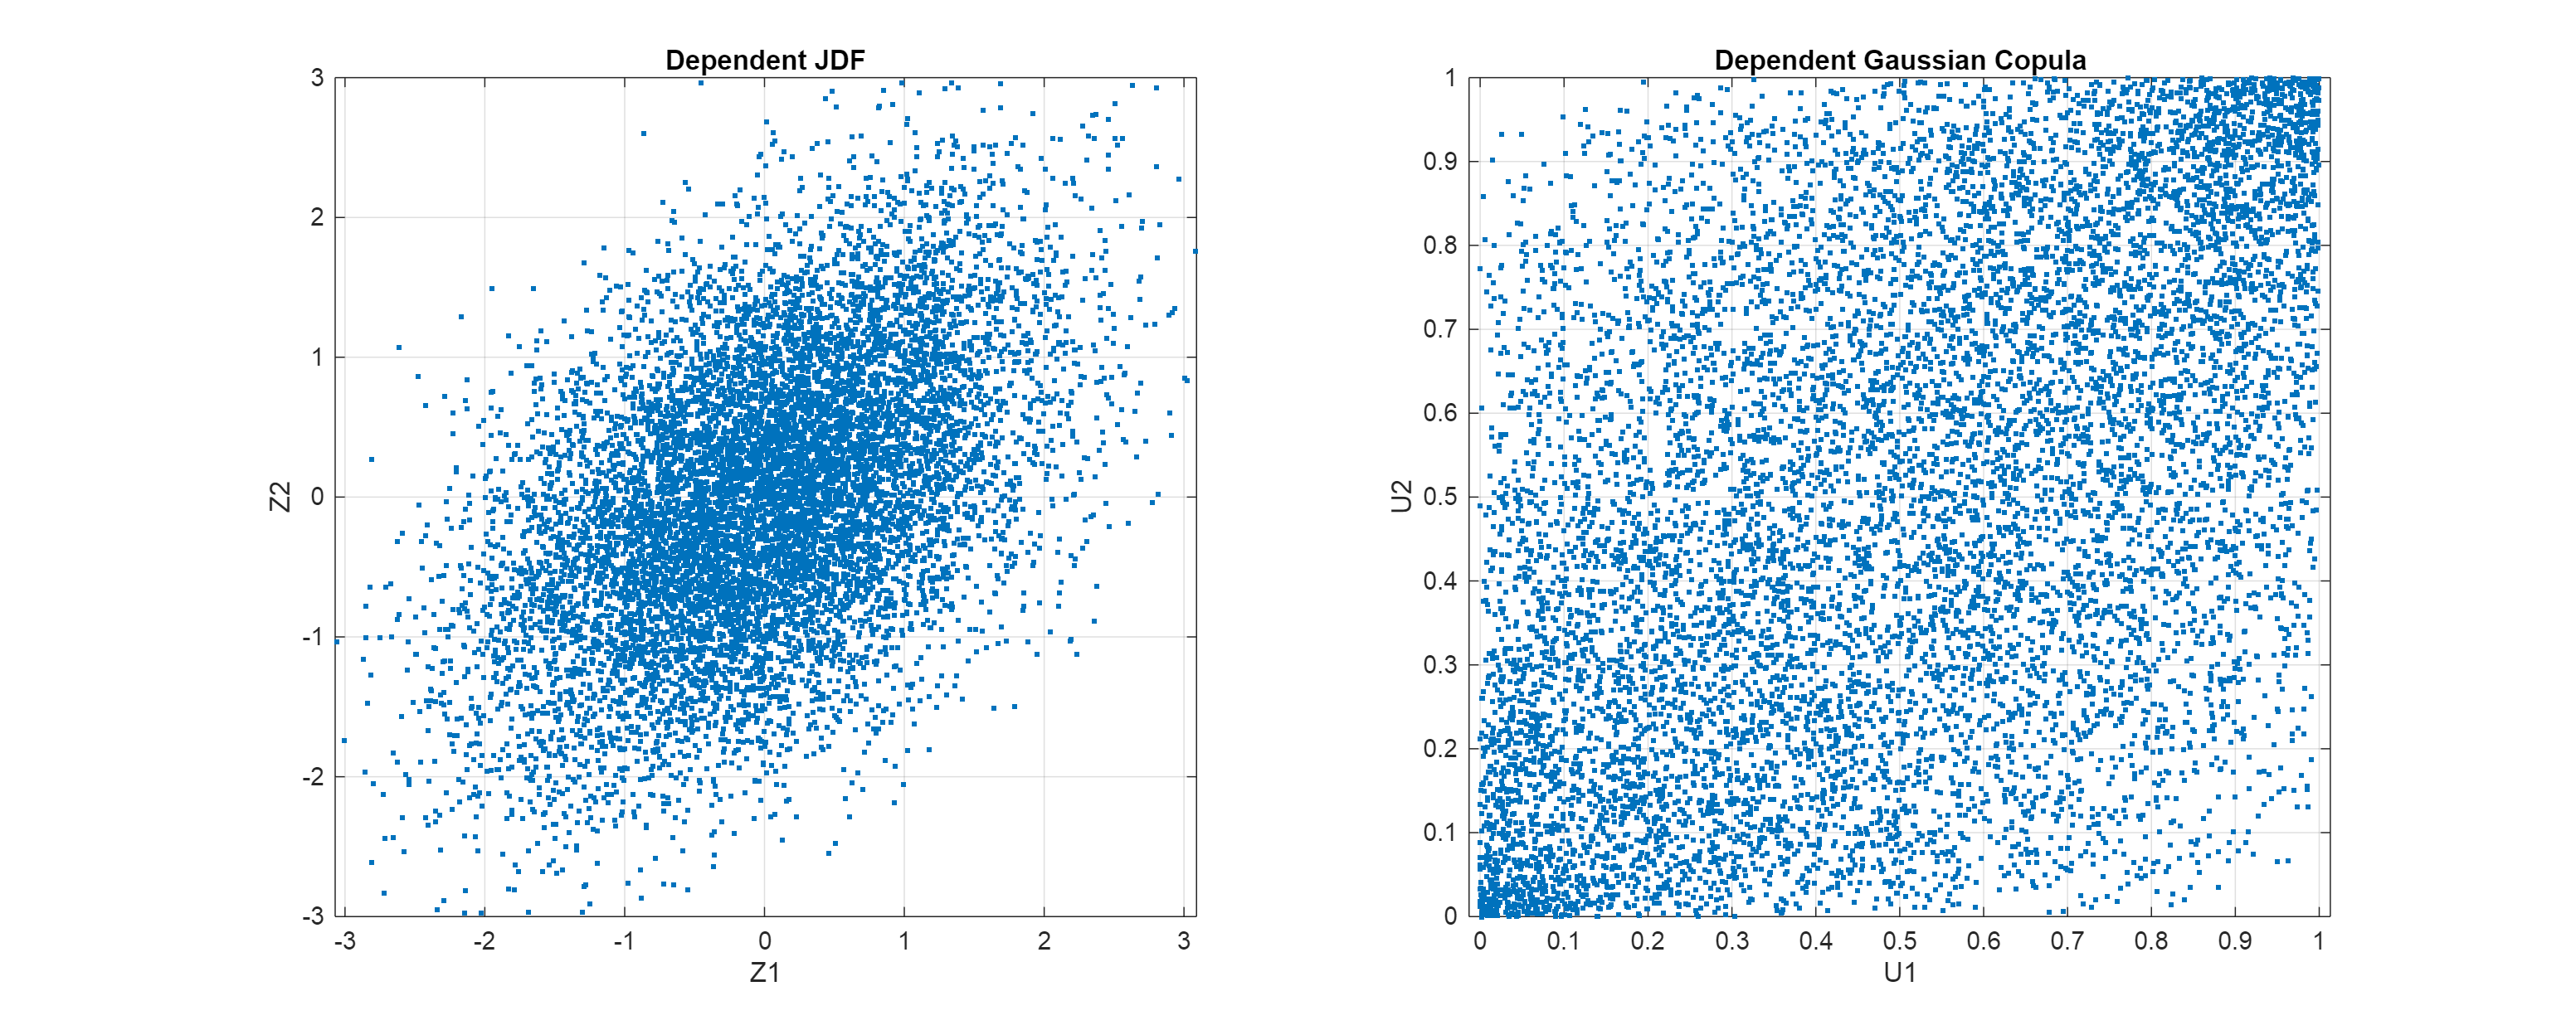

% Gaussian Copula Approach
UDEP_GaussianCopula = copularnd('Gaussian', CDEP, N);
ZDEP_GaussianCopula = norminv(UDEP_GaussianCopula);

% Graphs and Results
ISample = 1:10000; % to reduce the memory to display scatterplots

figure()
set(gcf, 'Position', [0,0,1500,600])
 
subplot(1,2,1)
plot(ZDEP_GaussianCopula(ISample,1), ZDEP_GaussianCopula(ISample,2), '.')
axis([-3 3 -3 3])
axis equal
grid on
title('Dependent JDF')
xlabel('Z1')
ylabel('Z2')
 
subplot(1,2,2)
plot(UDEP_GaussianCopula(ISample,1), UDEP_GaussianCopula(ISample,2), '.')
axis([0 1 0 1])
axis equal
grid on
title('Dependent Gaussian Copula')
xlabel('U1')
ylabel('U2')

### Expected Credit Loss and 99% Percentile of Loss Distribution

% Value of two BBB bonds
NBonds = 2;
ExpectedValue_Bond = sum(ExpectedValue) % using expected (transition) value of current BBB cond

ExpectedValue_Bond = 107.0879

ExpectedValue_Bond2 = NBonds * ExpectedValue_Bond

ExpectedValue_Bond2 = 214.1758

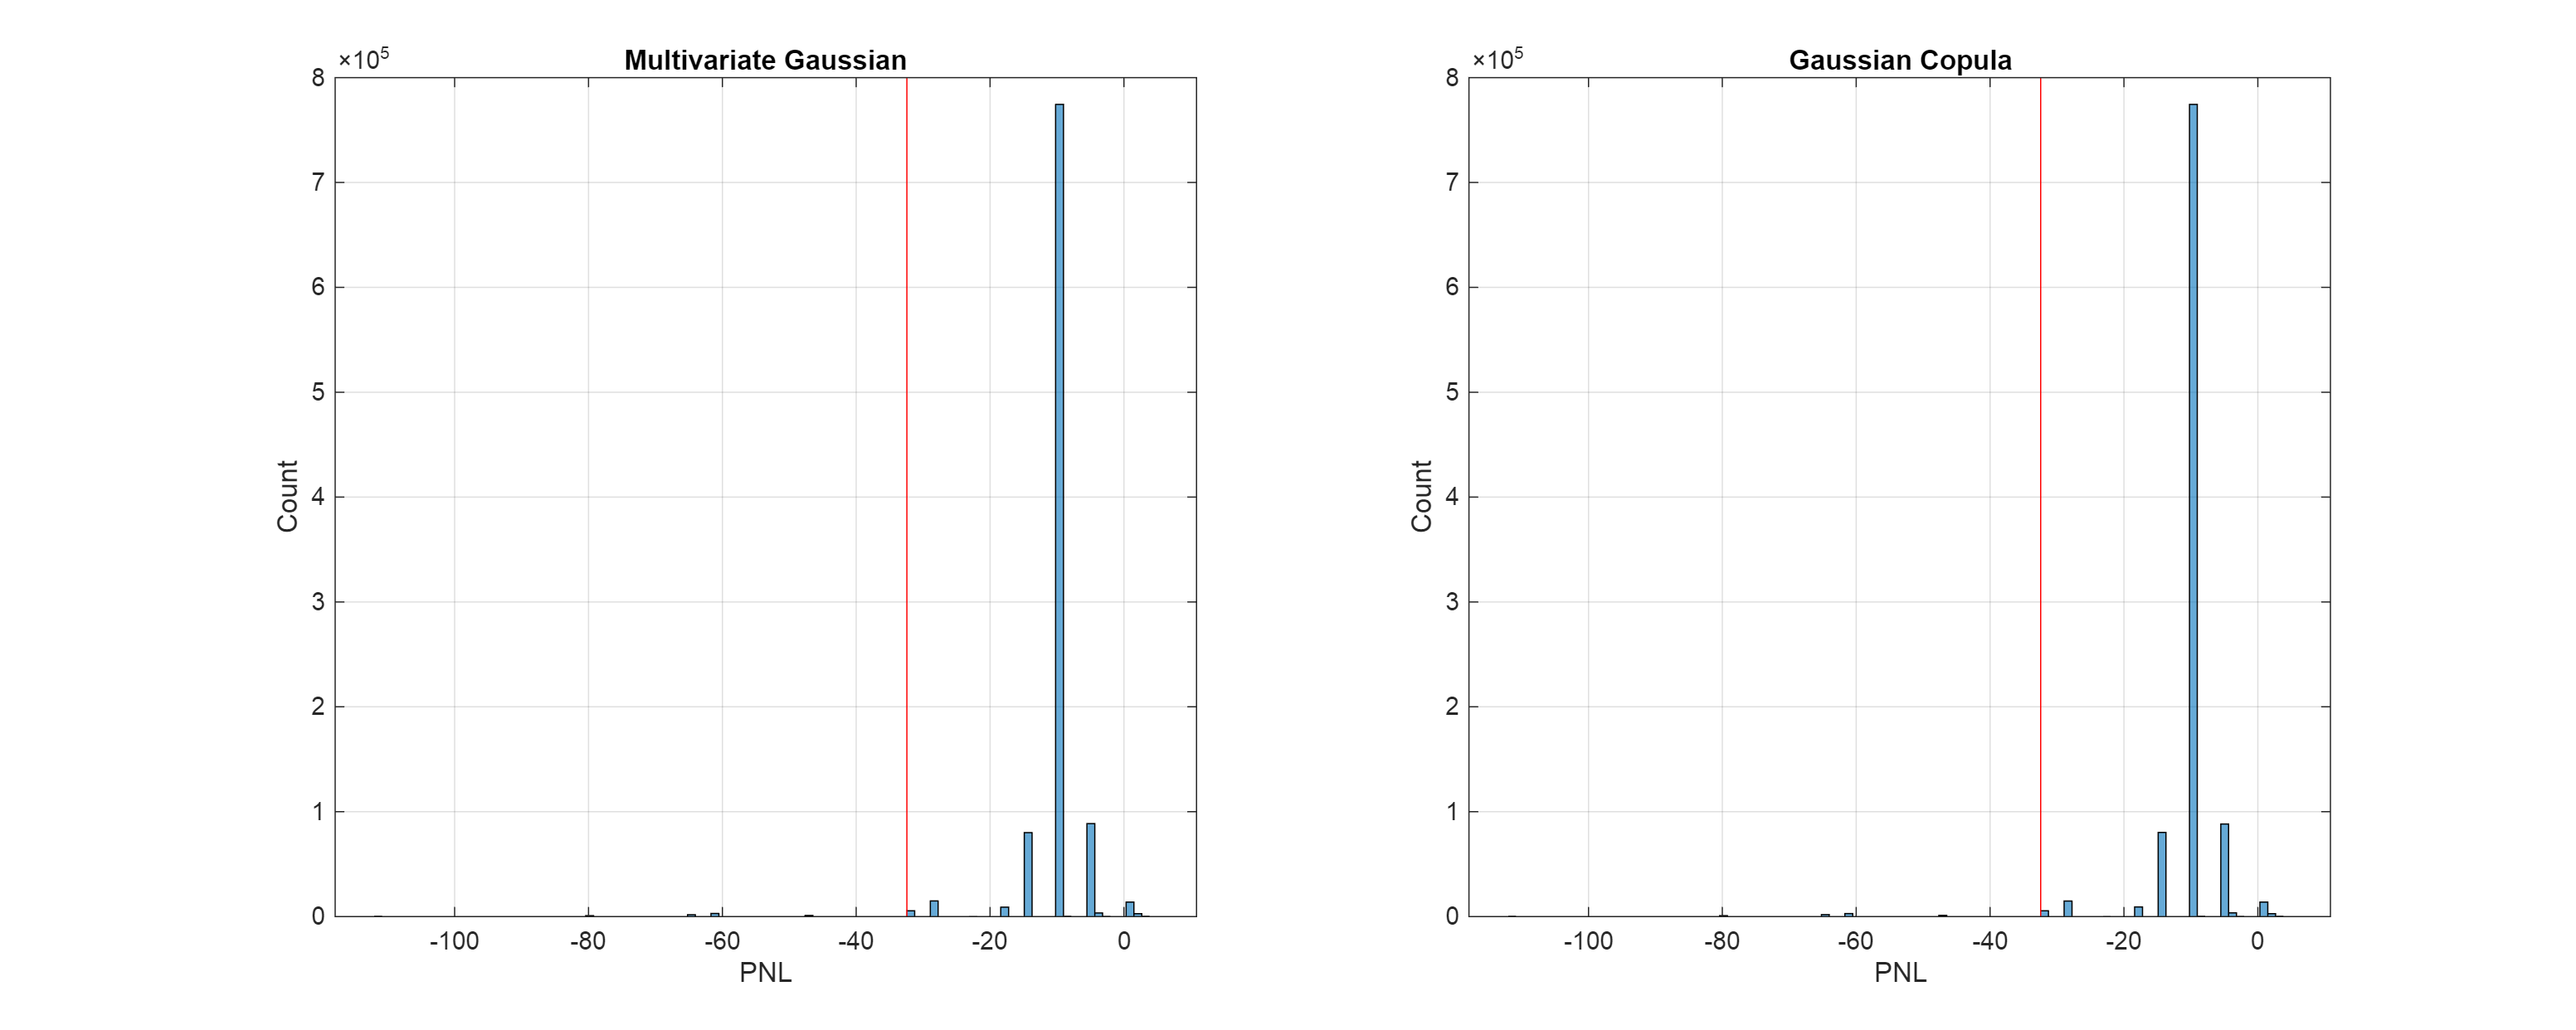

% A uniform version of the z-boundaries in this variable 
CumProbabilityBoundary = [CumProbability; 0];

% Prepare some storage variables
FutureBondValueDEP_MultiGaussian = NaN(N,2);
FutureBondValueDEP_GaussianCopula = NaN(N,2);

for i = 1:N
    % Multivariate Gaussian Distribution
    %% No need to -1 since the current finding index approach matches CumProbability and BondValue well
    IZ1 = find(CumProbabilityBoundary <= UDEP_MultiGaussian(i,1), 1, "first");
    IZ2 = find(CumProbabilityBoundary <= UDEP_MultiGaussian(i,2), 1, "first");
    FutureBondValueDEP_MultiGaussian(i,:) = [BondValue(min(IZ1,8)), BondValue(min(IZ2,8))];
    % Gaussian Copula
    IZ1 = find(CumProbabilityBoundary <= UDEP_GaussianCopula(i,1), 1, "first");
    IZ2 = find(CumProbabilityBoundary <= UDEP_GaussianCopula(i,2), 1, "first");
    FutureBondValueDEP_GaussianCopula(i,:) = [BondValue(min(IZ1,8)), BondValue(min(IZ2,8))];
end%for j
 
% Portfolio PNL
PortfolioDEP_MultiGaussian = sum(FutureBondValueDEP_MultiGaussian, 2) - NBonds * ExpectedValue_Bond; 
PortfolioDEP_GaussianCopula = sum(FutureBondValueDEP_GaussianCopula, 2) - NBonds * ExpectedValue_Bond;
% Expected Credit Loss
MultiGaussian_EL = mean(PortfolioDEP_MultiGaussian);
GaussianCopula_EL = mean(PortfolioDEP_GaussianCopula);
% 99% Loss Estimates
MultiGaussian_VAR99 = prctile(PortfolioDEP_MultiGaussian, 1); % This should be 1 instead of 0.1
GaussianCopula_VAR99 = prctile(PortfolioDEP_GaussianCopula, 1);

% Portfolio Returns
PortfolioDEP_MultiGaussian_return = sum(FutureBondValueDEP_MultiGaussian, 2) / (NBonds * ExpectedValue_Bond) - 1; 
PortfolioDEP_GaussianCopula_return = sum(FutureBondValueDEP_GaussianCopula, 2) / (NBonds * ExpectedValue_Bond) - 1;
% Expected Credit Loss
MultiGaussian_EL_return = mean(PortfolioDEP_MultiGaussian_return);
GaussianCopula_EL_return = mean(PortfolioDEP_GaussianCopula_return);
% 99% Loss Estimates
MultiGaussian_VAR99_return = prctile(PortfolioDEP_MultiGaussian_return, 1);
GaussianCopula_VAR99_return = prctile(PortfolioDEP_GaussianCopula_return, 1);

% Graphs and Results
figure()
set(gcf,'Position',[0,0,1500,600])

subplot(1,2,1)
histogram(PortfolioDEP_MultiGaussian,100)
hold on; line([MultiGaussian_VAR99,MultiGaussian_VAR99], get(gca,'YLim'), 'color', 'r'); hold off
title('Multivariate Gaussian')
ylabel('Count')
xlabel('PNL')
grid on

subplot(1,2,2)
histogram(PortfolioDEP_GaussianCopula,100)
hold on; line([GaussianCopula_VAR99,GaussianCopula_VAR99], get(gca,'YLim'), 'color', 'r'); hold off
title('Gaussian Copula')
ylabel('Count')
xlabel('PNL')
grid on

% Display the results for pnl
fprintf('Expected Credit Loss (Multivariate Gaussian): $%.8f\n', MultiGaussian_EL);

Expected Credit Loss (Multivariate Gaussian): $-10.57836314


fprintf('Expected Credit Loss (Gaussian Copula): $%.8f\n', GaussianCopula_EL);

Expected Credit Loss (Gaussian Copula): $-10.58577565


fprintf('99%% Percentile of Loss Distribution (Multivariate Gaussian): $%.8f\n', MultiGaussian_VAR99);

99% Percentile of Loss Distribution (Multivariate Gaussian): $-32.43583600


fprintf('99%% Percentile of Loss Distribution (Gaussian Copula): $%.8f\n', GaussianCopula_VAR99);

99% Percentile of Loss Distribution (Gaussian Copula): $-32.43583600


% Display the results for returns
fprintf('Expected Credit Loss (Multivariate Gaussian): %.6f%%\n', MultiGaussian_EL_return);

Expected Credit Loss (Multivariate Gaussian): -0.049391%


fprintf('Expected Credit Loss (Gaussian Copula): %.6f%%\n', GaussianCopula_EL_return);

Expected Credit Loss (Gaussian Copula): -0.049426%


fprintf('99%% Percentile of Loss Distribution (Multivariate Gaussian): %.6f%%\n', MultiGaussian_VAR99_return);

99% Percentile of Loss Distribution (Multivariate Gaussian): -0.151445%


fprintf('99%% Percentile of Loss Distribution (Gaussian Copula): %.6f%%\n', GaussianCopula_VAR99_return);

99% Percentile of Loss Distribution (Gaussian Copula): -0.151445%


### Comparison between A and B

In this specific case, neither model significantly outperforms the other in terms of loss prediction. Both models yield very close values for the expected credit loss and the 99% Value at Risk.

- **Expected Credit Loss**: Both models provide almost identical expected credit loss values. This similarity suggests that, for the central part of the distribution, both the multivariate Gaussian and the Gaussian copula with Gaussian marginals are capturing the dependency structure in a very similar way, although the multivariate Gaussian seems slightly higher than the Gaussian copula after a few decimal points.

- **99% Percentile of Loss Distribution**: The 99% percentile loss values (Value at Risk) are also nearly identical. This indicates that the tail dependencies, in this case, are quite similar between the two models when using Gaussian marginals with a Gaussian copula.

The similarity arises because both the multivariate Gaussian and the Gaussian copula with Gaussian marginals rely on the Gaussian dependency structure. The Gaussian distribution and Gaussian copula do not produce strong tail dependencies (extreme co-movements), so they behave similarly in credit risk modeling where more extreme tail dependence might yield different results.

If we had used a different copula (such as a t-copula) with stronger tail dependencies, the Gaussian copula model might produce higher loss predictions in the tails due to capturing joint extreme events more accurately. However, in this scenario, since both models are Gaussian-based, the results are very similar.

### Loss Prediction against Number of Bonds

% Number of simulations and correlation
N = 1e6;
DefaultRho = 0.5;

% Define bond counts to analyze
bond_counts = [2, 5, 10, 20, 30, 40, 50, 60, 70, 80, 90, 100];
num_bond_counts = length(bond_counts);

% Initialize storage for 99% VaR and Expected Credit Loss for each bond count
MultiGaussian_VAR99_values = zeros(1, num_bond_counts);
GaussianCopula_VAR99_values = zeros(1, num_bond_counts);
MultiGaussian_EL_values = zeros(1, num_bond_counts);
GaussianCopula_EL_values = zeros(1, num_bond_counts);
MultiGaussian_VAR99_return = zeros(1, num_bond_counts);
GaussianCopula_VAR99_return = zeros(1, num_bond_counts);
MultiGaussian_EL_return = zeros(1, num_bond_counts);
GaussianCopula_EL_return = zeros(1, num_bond_counts);

for b = 1:num_bond_counts
    NBonds = bond_counts(b);
    
    % Recompute the expected value for the given number of bonds
    ExpectedValue_Bond = sum(ExpectedValue);
    ExpectedValue_BondN = NBonds * ExpectedValue_Bond;
    
    % Create correlation matrix for NBonds bonds
    CDEP = DefaultRho * ones(NBonds) + (1 - DefaultRho) * eye(NBonds);
    
    % Simulate bond values using Multivariate Gaussian distribution
    ZDEP_MultiGaussian = mvnrnd(zeros(NBonds, 1), CDEP, N);
    UDEP_MultiGaussian = normcdf(ZDEP_MultiGaussian);
    
    % Simulate bond values using Gaussian Copula
    UDEP_GaussianCopula = copularnd('Gaussian', CDEP, N);
    
    % Initialize future bond values
    FutureBondValueDEP_MultiGaussian = NaN(N, NBonds);
    FutureBondValueDEP_GaussianCopula = NaN(N, NBonds);
    
    for i = 1:N
        for j = 1:NBonds
            % Multivariate Gaussian
            IZ = find(CumProbabilityBoundary <= UDEP_MultiGaussian(i, j), 1, "first");
            FutureBondValueDEP_MultiGaussian(i, j) = BondValue(min(IZ, 8));
            
            % Gaussian Copula
            IZ = find(CumProbabilityBoundary <= UDEP_GaussianCopula(i, j), 1, "first");
            FutureBondValueDEP_GaussianCopula(i, j) = BondValue(min(IZ, 8));
        end
    end
    
    % Calculate portfolio P&L
    PortfolioDEP_MultiGaussian = sum(FutureBondValueDEP_MultiGaussian, 2) - ExpectedValue_BondN;
    PortfolioDEP_GaussianCopula = sum(FutureBondValueDEP_GaussianCopula, 2) - ExpectedValue_BondN;
    % Calculate Expected Credit Loss (Mean P&L) for each model
    MultiGaussian_EL_values(b) = mean(PortfolioDEP_MultiGaussian);
    GaussianCopula_EL_values(b) = mean(PortfolioDEP_GaussianCopula);
    % Calculate 99% VaR for each model
    MultiGaussian_VAR99_values(b) = prctile(PortfolioDEP_MultiGaussian, 1);
    GaussianCopula_VAR99_values(b) = prctile(PortfolioDEP_GaussianCopula, 1);

    % Calculate portfolio return
    PortfolioDEP_MultiGaussian_return = sum(FutureBondValueDEP_MultiGaussian, 2) / ExpectedValue_BondN - 1;
    PortfolioDEP_GaussianCopula_return = sum(FutureBondValueDEP_GaussianCopula, 2) / ExpectedValue_BondN - 1;
    % Calculate Expected Credit Loss (Mean P&L) for each model
    MultiGaussian_EL_return(b) = mean(PortfolioDEP_MultiGaussian_return);
    GaussianCopula_EL_return(b) = mean(PortfolioDEP_GaussianCopula_return);
    % Calculate 99% VaR for each model
    MultiGaussian_VAR99_return(b) = prctile(PortfolioDEP_MultiGaussian_return, 1);
    GaussianCopula_VAR99_return(b) = prctile(PortfolioDEP_GaussianCopula_return, 1);
end

% Display a note on units
fprintf('Note: Expected Credit Loss and VaR values are expressed in units of profit and loss (dollar).\n\n');

Note: Expected Credit Loss and VaR values are expressed in units of profit and loss (dollar).



% Display Expected Credit Loss for each bond count in percentage
fprintf('Expected Credit Loss for Multivariate Gaussian:\n');

Expected Credit Loss for Multivariate Gaussian:


for b = 1:num_bond_counts
    fprintf('  %d bonds: $%.8f\n', bond_counts(b), MultiGaussian_EL_values(b));
end

  2 bonds: $-10.57202894
  5 bonds: $-26.45237533
  10 bonds: $-52.88176976
  20 bonds: $-105.80183024
  30 bonds: $-158.71745624
  40 bonds: $-211.67059406
  50 bonds: $-264.59802130
  60 bonds: $-317.52233662
  70 bonds: $-370.57940035
  80 bonds: $-423.11803951
  90 bonds: $-476.43967028
  100 bonds: $-528.95138169


fprintf('\nExpected Credit Loss for Gaussian Copula:\n');


Expected Credit Loss for Gaussian Copula:


for b = 1:num_bond_counts
    fprintf('  %d bonds: $%.8f\n', bond_counts(b), GaussianCopula_EL_values(b));
end

  2 bonds: $-10.58690457
  5 bonds: $-26.47687989
  10 bonds: $-52.89344246
  20 bonds: $-105.77667100
  30 bonds: $-158.74814358
  40 bonds: $-211.67242370
  50 bonds: $-264.61186976
  60 bonds: $-317.55035592
  70 bonds: $-370.35414250
  80 bonds: $-423.35176738
  90 bonds: $-476.08257188
  100 bonds: $-529.48615503



% Display 99% Percentile Expected Credit Loss for each bond count in percentage
fprintf('\n99%% Percentile Expected Credit Loss for Multivariate Gaussian:\n');


99% Percentile Expected Credit Loss for Multivariate Gaussian:


for b = 1:num_bond_counts
    fprintf('  %d bonds: $%.8f\n', bond_counts(b), MultiGaussian_VAR99_values(b));
end

  2 bonds: $-32.43583600
  5 bonds: $-80.14959000
  10 bonds: $-139.54918000
  20 bonds: $-264.96836000
  30 bonds: $-392.75754000
  40 bonds: $-516.62672000
  50 bonds: $-645.96590000
  60 bonds: $-770.16508000
  70 bonds: $-898.84426000
  80 bonds: $-1020.75344000
  90 bonds: $-1148.79262000
  100 bonds: $-1268.93680000


fprintf('\n99%% Percentile Expected Credit Loss for Gaussian Copula:\n');


99% Percentile Expected Credit Loss for Gaussian Copula:


for b = 1:num_bond_counts
    fprintf('  %d bonds: $%.8f\n', bond_counts(b), GaussianCopula_VAR99_values(b));
end

  2 bonds: $-32.43583600
  5 bonds: $-80.14959000
  10 bonds: $-139.54918000
  20 bonds: $-267.33836000
  30 bonds: $-391.53754000
  40 bonds: $-518.50672000
  50 bonds: $-643.26590000
  60 bonds: $-769.83508000
  70 bonds: $-893.37426000
  80 bonds: $-1018.79344000
  90 bonds: $-1144.54262000
  100 bonds: $-1274.70180000



% Display a note on units
fprintf('Note: Expected Credit Loss and VaR values are expressed in units of bond returns (percentage).\n\n');

Note: Expected Credit Loss and VaR values are expressed in units of bond returns (percentage).



% Display Expected Credit Loss for each bond count in percentage
fprintf('Expected Credit Loss for Multivariate Gaussian:\n');

Expected Credit Loss for Multivariate Gaussian:


for b = 1:num_bond_counts
    fprintf('  %d bonds: %.6f%%\n', bond_counts(b), MultiGaussian_EL_return(b) * 100);
end

  2 bonds: -4.936145%
  5 bonds: -4.940310%
  10 bonds: -4.938164%
  20 bonds: -4.939952%
  30 bonds: -4.940410%
  40 bonds: -4.941514%
  50 bonds: -4.941697%
  60 bonds: -4.941770%
  70 bonds: -4.943594%
  80 bonds: -4.938910%
  90 bonds: -4.943391%
  100 bonds: -4.939412%


fprintf('\nExpected Credit Loss for Gaussian Copula:\n');


Expected Credit Loss for Gaussian Copula:


for b = 1:num_bond_counts
    fprintf('  %d bonds: %.6f%%\n', bond_counts(b), GaussianCopula_EL_return(b) * 100);
end

  2 bonds: -4.943090%
  5 bonds: -4.944886%
  10 bonds: -4.939254%
  20 bonds: -4.938777%
  30 bonds: -4.941365%
  40 bonds: -4.941557%
  50 bonds: -4.941956%
  60 bonds: -4.942206%
  70 bonds: -4.940589%
  80 bonds: -4.941638%
  90 bonds: -4.939685%
  100 bonds: -4.944406%



% Display 99% Percentile Expected Credit Loss for each bond count in percentage
fprintf('\n99%% Percentile Expected Credit Loss for Multivariate Gaussian:\n');


99% Percentile Expected Credit Loss for Multivariate Gaussian:


for b = 1:num_bond_counts
    fprintf('  %d bonds: %.6f%%\n', bond_counts(b), MultiGaussian_VAR99_return(b) * 100);
end

  2 bonds: -15.144489%
  5 bonds: -14.968932%
  10 bonds: -13.031272%
  20 bonds: -12.371534%
  30 bonds: -12.225392%
  40 bonds: -12.060808%
  50 bonds: -12.064216%
  60 bonds: -11.986492%
  70 bonds: -11.990739%
  80 bonds: -11.914900%
  90 bonds: -11.919517%
  100 bonds: -11.849486%


fprintf('\n99%% Percentile Expected Credit Loss for Gaussian Copula:\n');


99% Percentile Expected Credit Loss for Gaussian Copula:


for b = 1:num_bond_counts
    fprintf('  %d bonds: %.6f%%\n', bond_counts(b), GaussianCopula_VAR99_return(b) * 100);
end

  2 bonds: -15.144489%
  5 bonds: -14.968932%
  10 bonds: -13.031272%
  20 bonds: -12.482191%
  30 bonds: -12.187417%
  40 bonds: -12.104697%
  50 bonds: -12.013790%
  60 bonds: -11.981356%
  70 bonds: -11.917768%
  80 bonds: -11.892021%
  90 bonds: -11.875420%
  100 bonds: -11.903320%


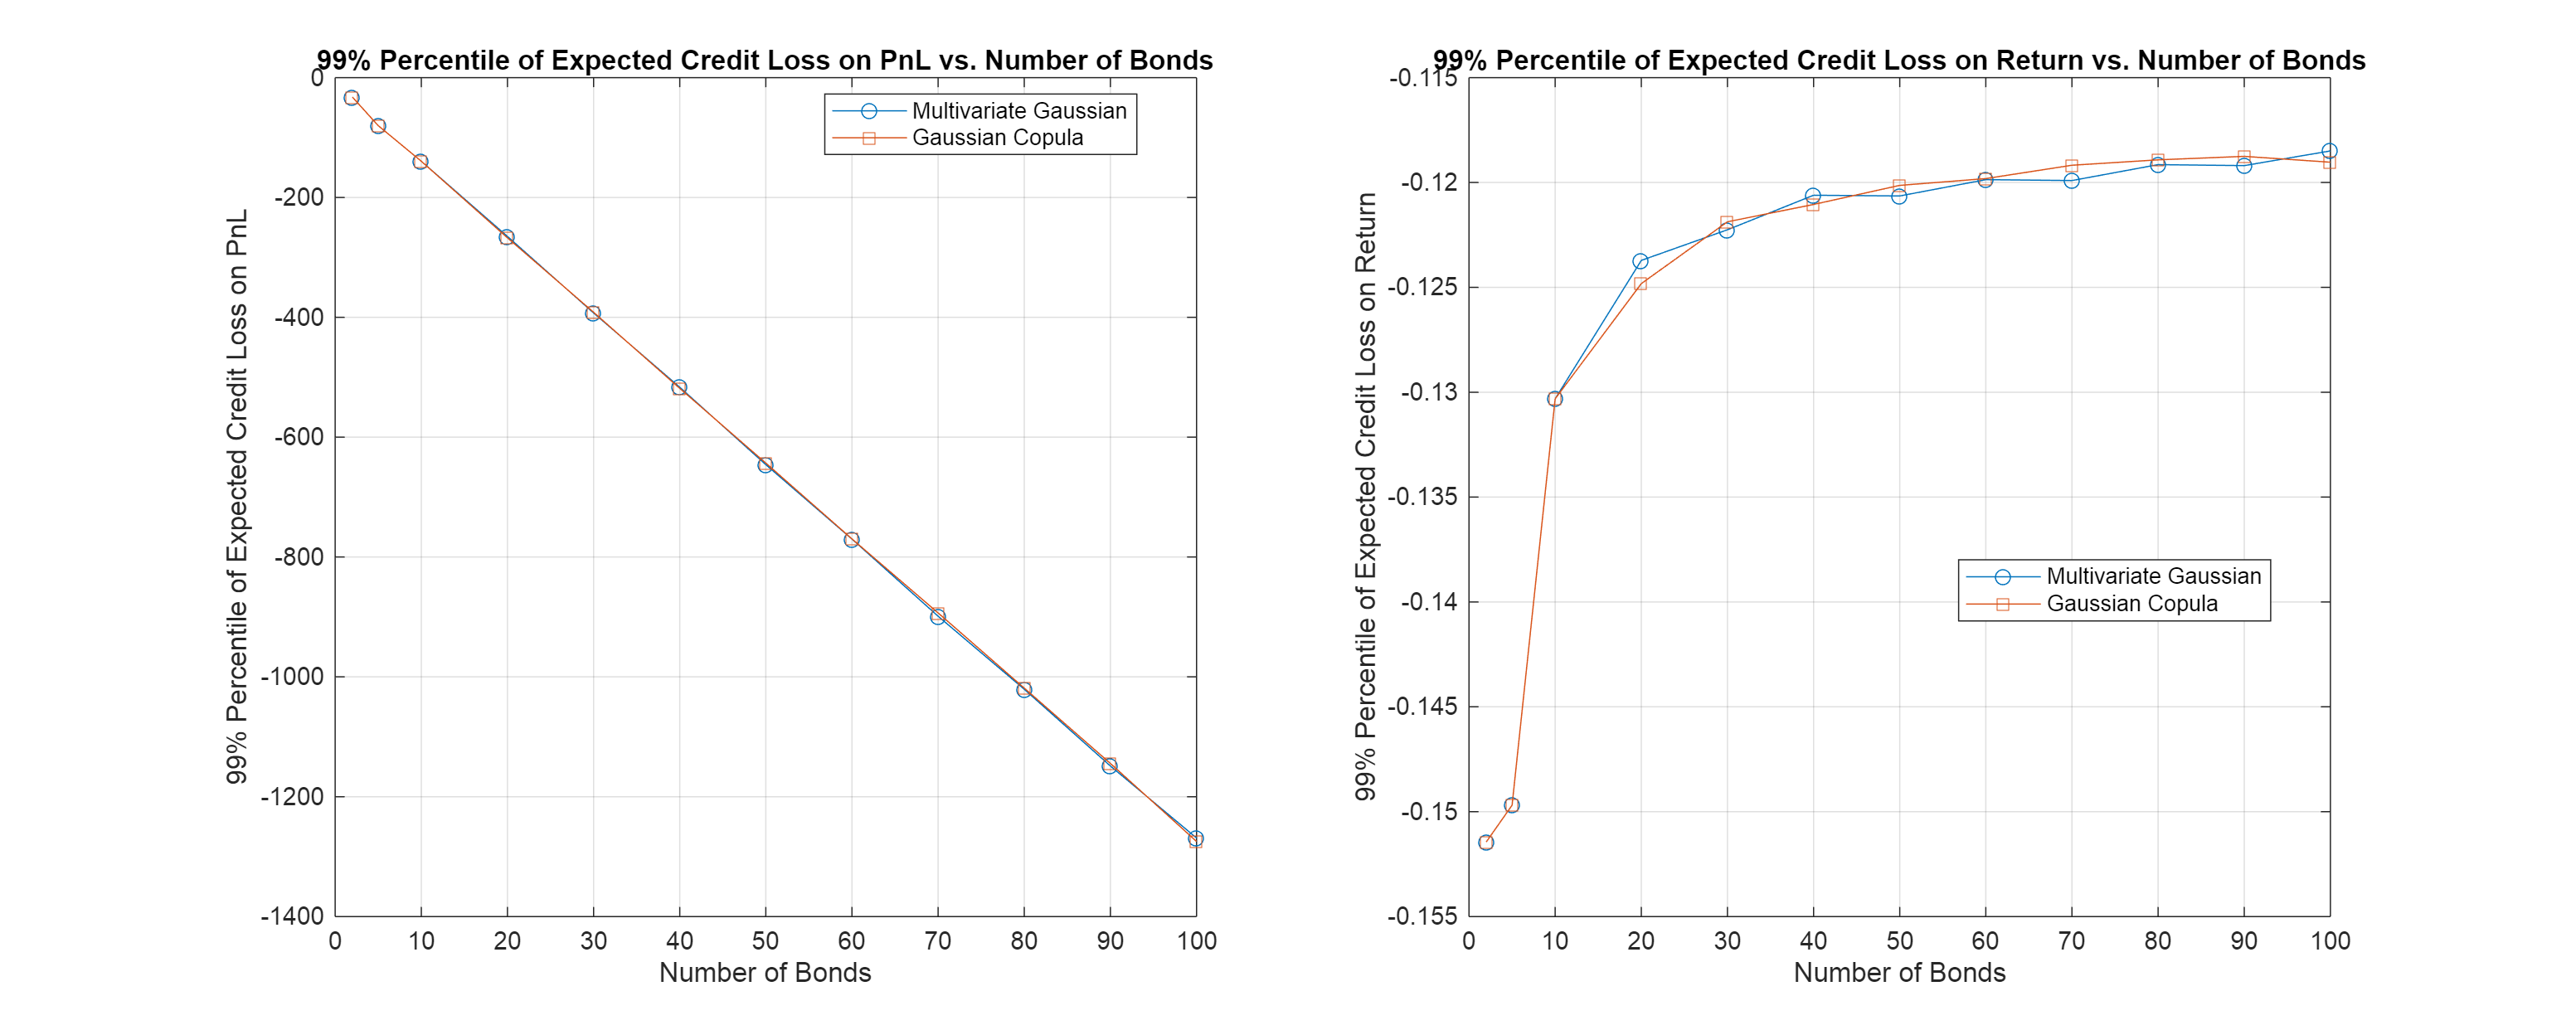

% Plot results for 99% VaR
figure()
set(gcf,'Position',[0,0,1500,600])

% PnL
subplot(1,2,1)
plot(bond_counts, MultiGaussian_VAR99_values, '-o', 'DisplayName', 'Multivariate Gaussian');
hold on;
plot(bond_counts, GaussianCopula_VAR99_values, '-s', 'DisplayName', 'Gaussian Copula');
xlabel('Number of Bonds');
ylabel('99% Percentile of Expected Credit Loss on PnL');
title('99% Percentile of Expected Credit Loss on PnL vs. Number of Bonds');
legend('Location', 'Best');
grid on;
hold off;

% Return
subplot(1,2,2)
plot(bond_counts, MultiGaussian_VAR99_return, '-o', 'DisplayName', 'Multivariate Gaussian');
hold on;
plot(bond_counts, GaussianCopula_VAR99_return, '-s', 'DisplayName', 'Gaussian Copula');
xlabel('Number of Bonds');
ylabel('99% Percentile of Expected Credit Loss on Return');
title('99% Percentile of Expected Credit Loss on Return vs. Number of Bonds');
legend('Location', 'Best');
grid on;
hold off;